## Nucleation radius trend

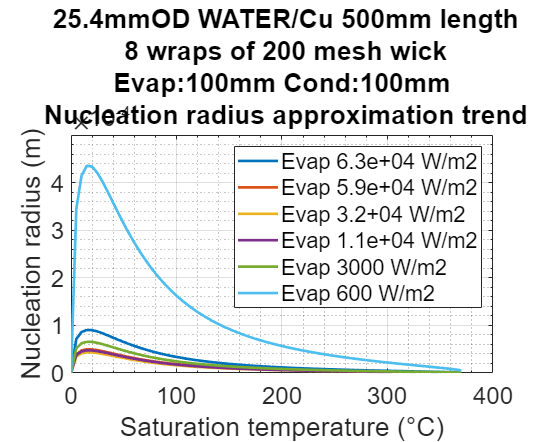


sz_qevap = size(q_evap);

for x = 1:sz_qevap(1);
    
r_n = sqrt((((st_l.*T').*K_l).*(dvx.^-1-rho_l.^-1))./(lhc*(q_evap(x))));

R_n(:,x) = r_n;

end

sz_q = size(q_evap);
spacing = round(linspace(1,sz_q(1),6));

figure9 = figure('Name','Figure','Color',[1 1 1],'OuterPosition',[31 137 1128 914]);

% Create axes
axes1 = axes('Parent',figure9);
hold(axes1,'on');

plot1 = plot(T,[R_n(:,spacing(1)),R_n(:,spacing(2)),R_n(:,spacing(3)),R_n(:,spacing(4)),R_n(:,spacing(5)),R_n(:,spacing(6))],'Parent',axes1);
set(plot1(1),'DisplayName','Evap 6.3e+04 W/m2','LineWidth',2);
set(plot1(2),'DisplayName','Evap 5.9e+04 W/m2','LineWidth',2);
set(plot1(3),'DisplayName','Evap 3.2+04 W/m2','LineWidth',2);
set(plot1(4),'DisplayName','Evap 1.1e+04 W/m2','LineWidth',2);
set(plot1(5),'DisplayName','Evap 3000 W/m2','LineWidth',2);
set(plot1(6),'DisplayName','Evap 600 W/m2','LineWidth',2);

ylabel({'Nucleation radius (m)'});                              % Create ylabel
xlabel({'Saturation temperature (°C)'});                        % Create xlabel

Cap_name1 = strcat({' '},string(do_mm),'mmOD',{' '},string(NAME_FLUID),'/',string(NAME_METAL),{' '},string(l_mm),'mm length');
if WICK_TYPE == 'mesh'
    Cap_name2 = strcat({' '},string(NW),{' '},'wraps',{' '},'of',{' '},string(MESH_NUMBER),{' '},string(WICK_TYPE),{' '},'wick');
else
    Cap_name2 = strcat({' '},'With',{' '},string(WICK_TYPE),{' '},'wick');
end
Cap_name3 = strcat('Evap:',string(EVAP_Length),'mm',{' '},'Cond:',string(COND_Length),'mm');
Cap_name4 = strcat(' Heat pipe heat flux limiatations at ',{' '},string(theta),'° angle');

title({Cap_name1,Cap_name2,Cap_name3,' Nucleation radius approximation trend'});    

%xlim(axes1,[Tmin Tmax]);                            % X-limits of the axes
%ylim(axes1,[0 max(Qcap_90+10)]);                                  % Y-limits of the axes
box(axes1,'on');
set(axes1,'XMinorTick','on','YMinorTick','on')      % Set the remaining axes properties

% Create legend
legend1 = legend(axes1,'show');
set(legend1,'Location','northeast');

set(axes1,'FontSize',18,'XGrid','on','XMinorGrid','on','XMinorTick','on',...
    'YGrid','on','YMinorGrid','on','YMinorTick','on')